% Neural Net Tool Box
clearvars; close all; clc;


% Load Image to play with
file_path = 'D:\Dropbox\Data\7-29-20 neurons glut4 and actin\utrophin\';
file_name = 'cell_2_area_1_dz_20_r_0_1.tif';
image_stack = readtiff([file_path, file_name]);

% Handle a subset of the images to begin
image_subset = image_stack(:,:,1:1);

epsint = 0.02;
% Code Begins
% build random thetas
theta1 = rand(30, 50)*2*epsint - epsint;
theta2 = rand(1, 31)*2*epsint - epsint;


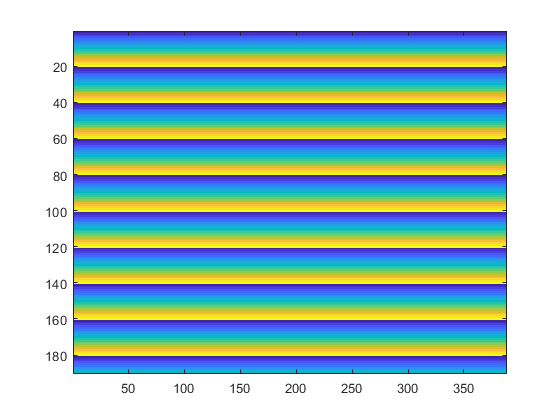

[a3] = image_neural_4(single(image_subset), theta1, theta2, 1);
imagesc(a3(:,:,1))